# Homework 5

Author: Simeon Karnes

Date: 2-27-2023

Problems: 1-3

## Nomenclature

- $\sigma_{\textrm{std}}$ is your theoretical RCS of the calibration sphere. $\sigma_{\mathrm{std}} =\pi r^2 \;\left(r=0\ldotp 125m\right)$

- ${\textrm{S21}}_{\textrm{lin}}$ is your VNA measurement in linear magnitude ${\textrm{S21}}_{\textrm{dBm}} ={10\;}^{\left(\frac{{\textrm{S21}}_{\textrm{dBm}} }{10}\right)}$

- ${\textrm{S21}}_{\textrm{dBm}}$ is your VNA measurement in dBm. ${\textrm{S21}}_{\textrm{dBm}} =10\;\log_{10} \left({\textrm{S21}}_{\textrm{lin}} \right)$

- ${\textrm{S21}}_{\textrm{std}}$ is your VNA measurement of the calibration sphere.

- ${\textrm{S21}}_{\textrm{tgt}}$ is your VNA measurement of the object (or target) whose RCS you are trying to calculate.

***        Examples***

- ${\textrm{S21}}_{\textrm{std},\textrm{lin}}$ would mean your VNA measurement of the calibration sphere in linear magnitude.

- ${\textrm{S21}}_{\textrm{std},\;\textrm{dBm}}$ would be your VNA measurement of the calibration sphere in dBm.

- ${\textrm{S21}}_{\textrm{tgt},\textrm{lin}}$ would be your VNA measurement of the target in linear magnitude.

- ${\textrm{S21}}_{\textrm{tgt},\textrm{dBm}}$ would be your VNA measurement of the target in linear magnitude.

## Calculating RCS

***Convert all linear VNA measurements to dBm.***

- $G_1$ and $G_2$ will refer to groups 1 (your group) and 2 (some other group) respectively.

- 
$${\textrm{S21}}_{G_1 ,\;\textrm{dBm}} =10\;\log_{10} \left({\textrm{S21}}_{G_1 ,\;\textrm{lin}} \right)$$


- 
$${\textrm{S21}}_{2,\;\textrm{dBm}} =10\;\log_{10} \left({\textrm{S21}}_{G_2 ,\;\textrm{lin}} \right)$$


***Calculate your ***$\sigma_{\textrm{std}}$***.***

- This value will be the same for all groups.

- $\sigma_{\textrm{std}} =\pi {\left(0\ldotp 125m\right)}^2 =0\ldotp 0490873852123405\ldotp \ldotp \ldotp m^2$ This is in linear.

***Calculate RCS by angle***

- 
$$\sigma_{\textrm{tgt},\textrm{lin}} =\sigma_{\textrm{std},\textrm{lin}} \;\;{10}^{\left(\frac{{\textrm{S21}}_{G_1 ,\textrm{lin}} -{\textrm{S21}}_{G_2 ,\textrm{lin}} }{10}\right)} =\textrm{RCS}\;\textrm{of}\;\textrm{sphere}\;\textrm{in}\;m^2 \;\textrm{for}\;\theta_i$$


## Housekeeping

close all; clear; clc;

## Data & Constants

sph_Group1 = readtable("RCS_Sphere.csv");
sph_Group2 = readtable("RCS_Sphere_Austin.csv");
uas = readtable("RCS_Drone.csv");

## Problem 1

Calculate the RCS for the calibration sphere used in class (radius = 0.125 m). Using another group’s calibration sphere data (Note: must use the same step size), create a table that has the received power (S21,std) for the eight orientations.

- Convert another group's sphere VNA measurements to dB.

- Calculate the mean and std dev across all frequencies for each angle of the dB

sph_S21_std_dBm_mean_Group2 = zeros(width(sph_Group1)-1,1);
sph_S21_std_dBm_stdev = zeros(width(sph_Group1)-1,1);
r_sph = 0.125; %m
sigma_std_lin = pi*(r_sph^2); % m^2

for j=2:width(sph_Group1)
    sph_S21_std_dBm_mean_Group2(j-1) = mean(10.*log10(table2array(sph_Group2(:,j))));
    sph_S21_std_dBm_stdev(j-1) = std(10*log10(table2array(sph_Group2(:,j))));
end

## Problem 2

Using the standard/calibration data from Problem 1 and the estimated RCS for the sphere, use your collected sphere data to create a polar plot of the RCS (of the sphere). How do your results match/compare to the theory? Example shown below.

*Calculate RCS of the sphere using your data and nother group's data. Ideally, the two data sets should be very close, which means your RCS should be *$1m^2$ or $0\;\textrm{dBsm}$

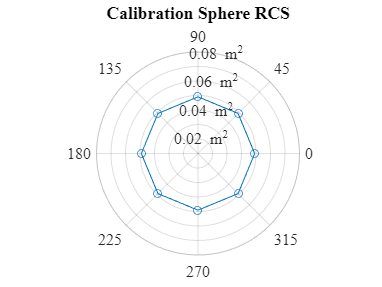

sph_S21_std_dBm_mean_Group1 = zeros(width(sph_Group1)-1,1);
sph_RCS_sph_lin = zeros(width(sph_Group1)-1,1);
for j=2:width(sph_Group1)
    sph_S21_std_dBm_mean_Group1(j-1) = mean(10.*log10(table2array(sph_Group1(:,j))));
    sph_RCS_sph_lin(j-1) = sigma_std_lin*10^((sph_S21_std_dBm_mean_Group2(j-1)-sph_S21_std_dBm_mean_Group1(j-1))/10);
end

figure('name','Problem 2 Answer');
polarplot([0:45:360].*(pi/180),sph_RCS_sph_lin,'o-');
title('Calibration Sphere RCS')
rticks([0.01:0.01:0.08]);
rticklabels({'','0.02 m^{2}','','0.04 m^{2}','','0.06 m^{2}','','0.08 m^{2}'});
rlim([0.01,0.08]);
thetaticks([0:45:360]);
set(gca,'fontname','Times New Roman');
set(gca,'fontsize',12);

## Problem 3

Using the VNA data collected from the baseline Skywalker X8 vehicle. Estimate the RCS polar plot (identical to Problem 2) for the Skywalker. What do you notice regarding the aircraft RCS?

*Repeat Problem 1 using YOUR skywalker data collected for *${\textrm{S21}}_{\textrm{tgt},\textrm{dBm}}$

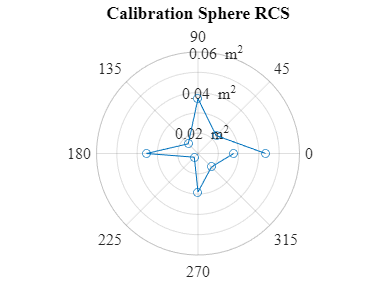

sph_S21_std_dBm_mean_X8 = zeros(width(sph_Group1)-1,1);
sph_RCS_X8_lin = zeros(width(sph_Group1)-1,1);
for j=2:width(sph_Group1)
    sph_S21_std_dBm_mean_X8(j-1) = mean(10.*log10(table2array(uas(:,j))));
    X8_RCS_lin(j-1) = sigma_std_lin*10^((sph_S21_std_dBm_mean_X8(j-1)-sph_S21_std_dBm_mean_Group1(j-1))/10);
end

figure('name','Problem 2 Answer');
polarplot([0:45:360].*(pi/180),X8_RCS_lin,'o-');
title('Calibration Sphere RCS')
rticks([0.01:0.01:0.06]);
rticklabels({'','0.02 m^{2}','','0.04 m^{2}','','0.06 m^{2}'});
rlim([0.01,0.06]);
thetaticks([0:45:360]);
set(gca,'fontname','Times New Roman');
set(gca,'fontsize',12);